A=[1,0;0,0.01];
[x,fun_val,iter]=gradient_method_backtracking(@(x)x'*A*x,@(x)2*A*x,...
[0.01;1],2,0.25,0.5,1e-5);

iter_number =   1 norm_grad = 0.028003 fun_val = 0.009704 
iter_number =   2 norm_grad = 0.027730 fun_val = 0.009324 
iter_number =   3 norm_grad = 0.027465 fun_val = 0.008958 
iter_number =   4 norm_grad = 0.027209 fun_val = 0.008608 
iter_number =   5 norm_grad = 0.026960 fun_val = 0.008271 
iter_number =   6 norm_grad = 0.026719 fun_val = 0.007947 
iter_number =   7 norm_grad = 0.026485 fun_val = 0.007636 
iter_number =   8 norm_grad = 0.026259 fun_val = 0.007338 
iter_number =   9 norm_grad = 0.026039 fun_val = 0.007051 
iter_number =  10 norm_grad = 0.025827 fun_val = 0.006776 
iter_number =  11 norm_grad = 0.025622 fun_val = 0.006512 
iter_number =  12 norm_grad = 0.025423 fun_val = 0.006258 
iter_number =  13 norm_grad = 0.025230 fun_val = 0.006014 
iter_number =  14 norm_grad = 0.025044 fun_val = 0.005780 
iter_number =  15 norm_grad = 0.024864 fun_val = 0.005555 
iter_number =  16 norm_grad = 0.024689 fun_val = 0.005339 
iter_number =  17 norm_grad = 0.024521 fun_val = 0.00513

x0 = [0.01; 1];
s = 2;
alpha = 0.25;
beta = 0.5;
epsilon = 1e-5;
9
a_values = 1./linspace(100, 2000, 20);
iters = zeros(size(a_values));

for i = 1:length(a_values)
    A = [1, 0; 0, a_values(i)];
    
    [x, ~, iter] = gradient_method_backtracking(@(x) x'*A*x, @(x) 2*A*x, x0, s, alpha, beta, epsilon);
    iters(i) = iter;
end

iter_number =   1 norm_grad = 0.028003 fun_val = 0.009704 
iter_number =   2 norm_grad = 0.027730 fun_val = 0.009324 
iter_number =   3 norm_grad = 0.027465 fun_val = 0.008958 
iter_number =   4 norm_grad = 0.027209 fun_val = 0.008608 
iter_number =   5 norm_grad = 0.026960 fun_val = 0.008271 
iter_number =   6 norm_grad = 0.026719 fun_val = 0.007947 
iter_number =   7 norm_grad = 0.026485 fun_val = 0.007636 
iter_number =   8 norm_grad = 0.026259 fun_val = 0.007338 
iter_number =   9 norm_grad = 0.026039 fun_val = 0.007051 
iter_number =  10 norm_grad = 0.025827 fun_val = 0.006776 
iter_number =  11 norm_grad = 0.025622 fun_val = 0.006512 
iter_number =  12 norm_grad = 0.025423 fun_val = 0.006258 
iter_number =  13 norm_grad = 0.025230 fun_val = 0.006014 
iter_number =  14 norm_grad = 0.025044 fun_val = 0.005780 
iter_number =  15 norm_grad = 0.024864 fun_val = 0.005555 
iter_number =  16 norm_grad = 0.024689 fun_val = 0.005339 
iter_number =  17 norm_grad = 0.024521 fun_val = 0.00513

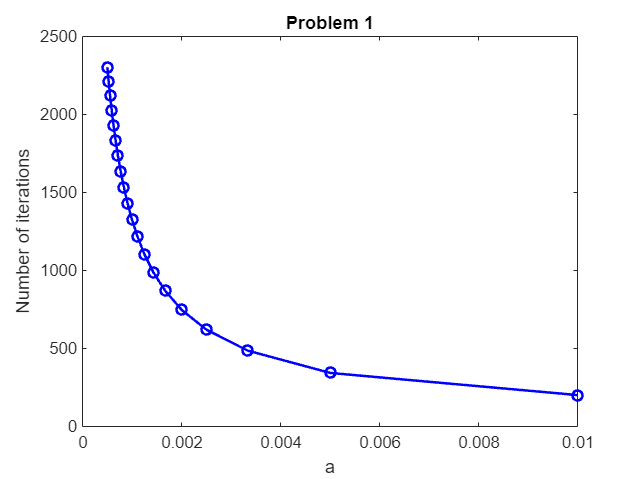


plot(a_values, iters, 'bo-', 'LineWidth', 1.5);
xlabel('a');
ylabel('Number of iterations');
title('Problem 1');